# Optimization and Data Analytics HW18

## Introduction to Machine Learning Course Notes sec. 3

## Exercise 3.1: Probability Decision

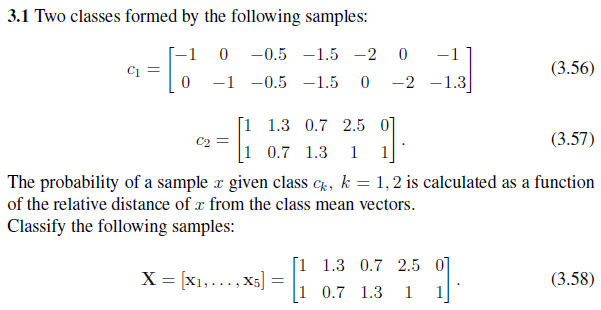

c1 = [  -1 0 -0.5 -1.5 -2 0 -1;
        0 -1 -0.5 -1.5 0 -2 -1.3]

c1 =    -1.0000         0   -0.5000   -1.5000   -2.0000         0   -1.0000
         0   -1.0000   -0.5000   -1.5000         0   -2.0000   -1.3000


[k,N(1)] = size(c1);

c2 = [  1 1.3 0.7 2.5 0;
        1 0.7 1.3 1 1]

c2 =     1.0000    1.3000    0.7000    2.5000         0
    1.0000    0.7000    1.3000    1.0000    1.0000


[k,N(2)] = size(c2);

% Apparently this sample data is wrong (from solutions)
% X = [1 1.3 0.7 2.5 0;
%    1 0.7 1.3 1 1]

X = [0 1 -1 0.7 -0.2;
    0 1 0 -0.2 1.5]

X =          0    1.0000   -1.0000    0.7000   -0.2000
         0    1.0000         0   -0.2000    1.5000


[k,NX] = size(X);
K = 2;

In probability-based learning, the goal is to estimate the probabilities of a given sample belonging to a given class, given it's value, and assign said value to the class with the highest probability. That is, for this exercise, determining the conditional probabilities $P\left(c_k |x\right)$, which is given by Bayes' decision rule:


$$P\left(c_k |x\right)=\frac{p\left(x|c_k \right)P\left(c_k \right)}{p\left(x\right)}=p\left(x|c_k \right)P\left(c_k \right)$$


Thus, we need to determine the *a priori* probability and the class-conditional probability density.

The *a priori* probability $P\left(c_k \right)$ is given by:


$$P\left(c_k \right)=\frac{N_k }{\sum_{l=1}^{K} N_l }$$


a_priori = [];
for i=1:K
   a_priori_prob(i) = N(i)/sum(N); 
end
a_priori_prob

a_priori_prob =     0.5833    0.4167


The class-conditional probability density determines the probability of observing the value x given its sample is classified as a given class $c_k$.The *class-conditional probability density *may be determined in multiple ways. The simplest is the euclidean distance:


$$p\left(x|c_k \right)=\frac{\left\|x-m_k \right\|}{\sum_{l=1}^{K} \left\|x-m_l \right\|}$$


Alternatively, it can be calculated using the exponential distance:


$$p\left(x|c_k \right)=\frac{\exp \left(\left\|x-m_k \right\|\right)}{\sum_{l=1}^{K} \exp \left(\left\|x-m_l \right\|\right)}$$


% Calculate class means along each dimension
mean1 = [mean(c1(1,:));
        mean(c1(2,:))]

mean1 =    -0.8571
   -0.9000



mean2 = [mean(c2(1,:));
        mean(c2(2,:))]

mean2 =     1.1000
    1.0000



% Calculate euclidean distances from class means
%x_c1_dist = sqrt(sum((X-mean1)'.^2, 2))'    % Norm of each column in X-mean1
x_c1_dist = vecnorm(X-mean1)

x_c1_dist =     1.2429    2.6569    0.9113    1.7072    2.4883


%x_c2_dist = sqrt(sum((X-mean2)'.^2, 2))'    % Norm of each column in X-mean2
x_c2_dist = vecnorm(X-mean2)

x_c2_dist =     1.4866    0.1000    2.3259    1.2649    1.3928


        
% Calculate the class-conditional probability density
    % Using euclidean distance
    %p_x_given_c1 = x_c1_dist ./ (x_c1_dist + x_c2_dist);
    %p_x_given_c2 = x_c2_dist ./ (x_c1_dist + x_c2_dist);
    
    % Using exponential distance
    p_x_given_c1 = exp(-x_c1_dist) ./ ( exp(-x_c1_dist) + exp(-x_c2_dist) );
    p_x_given_c2 = exp(-x_c2_dist) ./ ( exp(-x_c1_dist) + exp(-x_c2_dist) );
p_x_given_c = [p_x_given_c1;
               p_x_given_c2]

p_x_given_c =     0.5606    0.0720    0.8045    0.3912    0.2506
    0.4394    0.9280    0.1955    0.6088    0.7494


The conditional probability $P\left(c_k |x\right)$, which is given by Bayes' decision rule can now be calculated:


$$P\left(c_k |x\right)=\frac{p\left(x|c_k \right)P\left(c_k \right)}{p\left(x\right)}=p\left(x|c_k \right)P\left(c_k \right)$$


% Multiplying the a priori probability and the posteriori distribution element wise
P_c_given_x = a_priori_prob' .* p_x_given_c

P_c_given_x =     0.3270    0.0420    0.4693    0.2282    0.1462
    0.1831    0.3867    0.0815    0.2537    0.3123


The conditional probabilities determine the classification of each sample. To compare the probabilities, we simply find the difference between them with respect to *c1*. Thus, if the difference is positive the sample is classified as *c1, *and if it is negative the sample is classified as *c2*.

% Compare probabilties by evaluating difference
diff = P_c_given_x(1,:) - P_c_given_x(2,:)

diff =     0.1440   -0.3447    0.3878   -0.0255   -0.1661



class = zeros(1,NX);
for i=1:NX
    if diff(i) > 0
       class(i) = 1; 
    elseif diff(i) < 0
        class(i) = 2;
    else
        class(i) = 0;   % Classes are equally likely
    end
end
class

class =      1     2     1     2     2


## Exercise 3.2: Risk-Based Decision

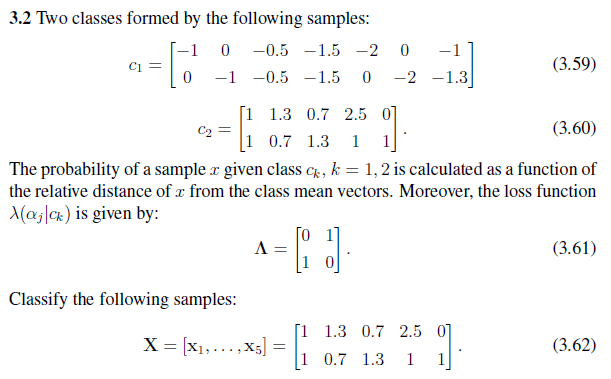

c1 = [  -1 0 -0.5 -1.5 -2 0 -1;
        0 -1 -0.5 -1.5 0 -2 -1.3]
[k,N(1)] = size(c1);

c2 = [  1 1.3 0.7 2.5 0;
        1 0.7 1.3 1 1]
[k,N(2)] = size(c2);

% Apparently this sample data is wrong (from solutions)
% X = [1 1.3 0.7 2.5 0;
%    1 0.7 1.3 1 1]

X = [0 1 -1 0.7 -0.2;
    0 1 0 -0.2 1.5]
[k,NX] = size(X);
K = 2;

loss = [0 1;
        1 0]  

In probability-based learning, the goal is to estimate the probabilities of a given sample belonging to a given class, given it's value, and assign said value to the class with the highest probability. That is, for this exercise, determining the conditional probabilities $P\left(c_k |x\right)$ and minimize the risk. The conditional probability is given by:


$$P\left(c_k |x\right)=\frac{p\left(x|c_k \right)P\left(c_k \right)}{p\left(x\right)}=p\left(x|c_k \right)P\left(c_k \right)$$


And the risk of a classification is given by the conditional probability and the loss function:


$$R\left(\alpha_1 |x\right)=\sum_{l=1}^{K} \lambda \left(\alpha_1 |c_k \right)P\left(c_k |x\right)$$


Thus, we need to determine the *a priori* probability and the class-conditional probability density.

The *a priori* probability $P\left(c_k \right)$ is given by:


$$P\left(c_k \right)=\frac{N_k }{\sum_{l=1}^{K} N_l }$$


a_priori = [];
for i=1:K
   a_priori_prob(i) = N(i)/sum(N); 
end
a_priori_prob

The class-conditional probability density determines the probability of observing the value x given its sample is classified as a given class $c_k$.The *class-conditional probability density *may be determined in multiple ways. The simplest is the euclidean distance:


$$p\left(x|c_k \right)\frac{\left\|x-m_k \right\|}{\sum_{l=1}^{K} \left\|x-m_l \right\|}$$


Alternatively, it can be calculated using the exponential distance:


$$p\left(x|c_k \right)\frac{\mathrm{exp}\left(\left\|x-m_k \right\|\right)}{\sum_{l=1}^{K} \mathrm{exp}\left(\left\|x-m_l \right\|\right)}$$


mean1 = [mean(c1(1,:));
        mean(c1(2,:))]

mean2 = [mean(c2(1,:));
        mean(c2(2,:))]

% Calculate euclidean distances from class means
%x_c1_dist = sqrt(sum((X-mean1)'.^2, 2))'    % Norm of each column
x_c1_dist = vecnorm(X-mean1)
%x_c2_dist = sqrt(sum((X-mean2)'.^2, 2))'    % Norm of each column
x_c2_dist = vecnorm(X-mean2)

% Calculate the class-conditional probability density
    % Using euclidean distance
    %p_x_given_c1 = x_c1_dist ./ (x_c1_dist + x_c2_dist);
    %p_x_given_c2 = x_c2_dist ./ (x_c1_dist + x_c2_dist);
    
    % Using exponential distance
    p_x_given_c1 = exp(-x_c1_dist) ./ ( exp(-x_c1_dist) + exp(-x_c2_dist) );
    p_x_given_c2 = exp(-x_c2_dist) ./ ( exp(-x_c1_dist) + exp(-x_c2_dist) );
p_x_given_c = [p_x_given_c1;
               p_x_given_c2]

The conditional probability $P\left(c_k |x\right)$, which is given by Bayes' decision rule can now be calculated:


$$P\left(c_k |x\right)=\frac{p\left(x|c_k \right)P\left(c_k \right)}{p\left(x\right)}=p\left(x|c_k \right)P\left(c_k \right)$$


% Multiplying the a priori probability and the posteriori distribution element wise
P_c_given_x = a_priori_prob' .* p_x_given_c

The classification of each sample is determined by minimizng the risk. This is done by calculating the risk from the conditional probability and the loss associated with classifying the sample wrong, and classifying samples by minimizing the risk:


$$R\left(\alpha_1 |x\right)=\sum_{l=1}^{K} \lambda \left(\alpha_1 |c_k \right)P\left(c_k |x\right)$$


% Calculate risk associated with classifying each sample
risk = loss*P_c_given_x

class = zeros(1,NX);
for i=1:NX
    if risk(1,i) < risk(2,i)
       class(i) = 1; 
    elseif risk(1,i) > risk(2,i)
        class(i) = 2;
    else
        class(i) = 0;   % Classes are equally likely
    end
end
class

## Exercise 3.3: Risk-Based Decision

loss = [0.3 0.8;
        0.7 0.2]    

The risk is calculated from the conditional probability and the loss function:


$$R\left(\alpha_1 |x\right)=\sum_{l=1}^{K} \lambda \left(\alpha_1 |c_k \right)P\left(c_k |x\right)$$


The conditional probability is found in exercise 3.2.

risk = loss*P_c_given_x

class = zeros(1,NX);
for i=1:NX
    if risk(1,i) < risk(2,i)
       class(i) = 1; 
    elseif risk(1,i) > risk(2,i)
        class(i) = 2;
    else
        class(i) = 0;   % Classes are equally likely
    end
end
class       

## Exercise 3.4: Decision Functions of the Normal Density

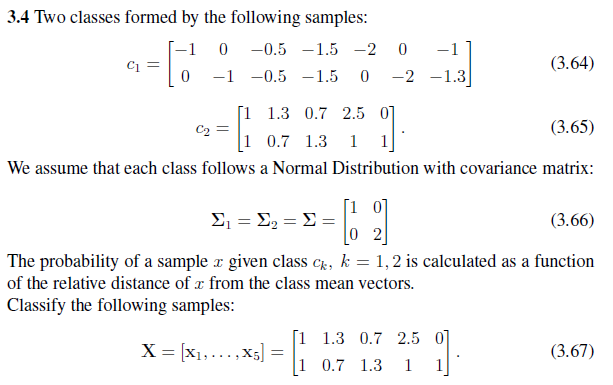

c1 = [  -1 0 -0.5 -1.5 -2 0 -1;
        0 -1 -0.5 -1.5 0 -2 -1.3]
[k,N(1)] = size(c1);

c2 = [  1 1.3 0.7 2.5 0;
        1 0.7 1.3 1 1]
[k,N(2)] = size(c2);

% Apparently this sample data is wrong (from solutions)
% X = [1 1.3 0.7 2.5 0;
%    1 0.7 1.3 1 1]

X = [0 1 -1 0.7 -0.2;
    0 1 0 -0.2 1.5]
[k,NX] = size(X);
K = 2;

covariance = [1 0;
              0 2];

Decision functions based on the normal density, make the assumption that the samples of unknown distribution can be modeled adequately by the normal distribution per the Central-Limit Theorem. The goal is to determine the conditional probability $P\left(c_k |x\right)$, and classify samples as the most likely class.


$$P\left(c_k |x\right)=\frac{p\left(x|c_k \right)P\left(c_k \right)}{p\left(x\right)}=p\left(x|c_k \right)P\left(c_k \right)$$


Thus, we need to determine the *a priori* probability and the class-conditional probability density.

The *a priori* probability $P\left(c_k \right)$ is given by:


$$P\left(c_k \right)=\frac{N_k }{\sum_{l=1}^{K} N_l }$$


a_priori = [];
for i=1:K
   a_priori_prob(i) = N(i)/sum(N); 
end
a_priori_prob

The class-conditional probability density determines the probability of observing the value x given its sample is classified as a given class $c_k$.The *class-conditional probability *is given by:

The class-conditional probability density $p\left(x|c_k \right)$ is given by:


$$p\left(x|c_k \right)=\frac{{\left(x-m_k \right)}^T \Sigma^{-1} \left(x-m_k \right)}{\sum_{l=1}^{K} {\left(x-m_l \right)}^T \Sigma^{-1} \left(x-m_l \right)}$$


Alternatively, it can be calculated using the exponential distance:


$$p\left(x|c_k \right)\frac{\exp \left({\left(x-m_k \right)}^T \Sigma^{-1} \left(x-m_k \right)\right)}{\sum_{l=1}^{K} \exp \left({\left(x-m_l \right)}^T \Sigma^{-1} \left(x-m_l \right)\right)}$$


% Calculate class means along each dimension
mean1 = [mean(c1(1,:));
        mean(c1(2,:))]

mean2 = [mean(c2(1,:));
        mean(c2(2,:))] 

% Calculate numerator assuming a normal distribution
x_c1_dist = zeros(1,NX);
x_c2_dist = zeros(1,NX);
for i=1:NX
    x_c1_dist(i) = (X(:,i)-mean1)' * covariance^-1 * (X(:,i)-mean1);                  
    x_c2_dist(i) = (X(:,i)-mean2)' * covariance^-1 * (X(:,i)-mean2);
end
x_c1_dist
x_c2_dist
        
% Calculate the class-conditional probability density
    % Using euclidean distance
    %p_x_given_c1 = x_c1_dist ./ (x_c1_dist + x_c2_dist);
    %p_x_given_c2 = x_c2_dist ./ (x_c1_dist + x_c2_dist);
    
    % Using exponential distance
    p_x_given_c1 = exp(-x_c1_dist) ./ ( exp(-x_c1_dist) + exp(-x_c2_dist) );
    p_x_given_c2 = exp(-x_c2_dist) ./ ( exp(-x_c1_dist) + exp(-x_c2_dist) );
p_x_given_c = [p_x_given_c1;
               p_x_given_c2]

The conditional probability $P\left(c_k |x\right)$, which is given by Bayes' decision rule can now be calculated:

% Multiplying the a priori probability and the posteriori distribution element wise
P_c_given_x = a_priori_prob' .* p_x_given_c

The conditional probabilities determine the classification of each sample. To compare the probabilities, we simply find the difference between them with respect to *c1*. Thus, if the difference is positive the sample is classified as *c1, *and if it is negative the sample is classified as *c2*.

% Compare probabilties by evaluating difference
diff = P_c_given_x(1,:) - P_c_given_x(2,:)

class = zeros(1,NX);
for i=1:NX
    if diff(i) > 0
       class(i) = 1; 
    elseif diff(i) < 0
        class(i) = 2;
    else
        class(i) = 0;   % Classes are equally likely
    end
end
class

## Exercise 3.5: Decision Functions of the Normal Density

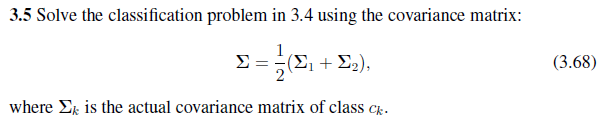

The initial step is to find the covariance matrx of each class.

The covariance matrix is given by:


$$\Sigma {\text{ }}_k =\sigma^2 \mathit{\mathbf{I}}$$


The variance of each class is given by:


$$\sigma^2 =E\left\lbrack {\left(X-\mu \right)}^2 \right\rbrack$$


% Calculate the centralized class samples
x_cent1 = c1 - (mean1*ones(1,N(1)));
x_cent2 = c2 - (mean2*ones(1,N(2)));

% Calculate the covariance of each class
Sigma1 = x_cent1*x_cent1'
Sigma2 = x_cent2*x_cent2'

The covariance matrix is then given by:


$$\Sigma =\frac{1}{2}\left(\Sigma {\text{ }}_1 +\Sigma {\text{ }}_2 \right)$$


covariance = (Sigma1 + Sigma2)/2

The class-conditional probability density $p\left(x|c_k \right)$ can now be calculated, as it is given by:


$$p\left(x|c_k \right)=\frac{{\left(x-m_k \right)}^T \Sigma^{-1} \left(x-m_k \right)}{\sum_{l=1}^{K} {\left(x-m_l \right)}^T \Sigma^{-1} \left(x-m_l \right)}$$


Alternatively, it can be calculated using the exponential distance:


$$p\left(x|c_k \right)\frac{\exp \left({\left(x-m_k \right)}^T \Sigma^{-1} \left(x-m_k \right)\right)}{\sum_{l=1}^{K} \exp \left({\left(x-m_l \right)}^T \Sigma^{-1} \left(x-m_l \right)\right)}$$


% Calculate euclidean distances from class means assuming a normal distribution
x_c1_dist = zeros(1,NX);
x_c2_dist = zeros(1,NX);
for i=1:NX
    x_c1_dist(i) = (X(:,i)-mean1)' * covariance^-1 * (X(:,i)-mean1);                  
    x_c2_dist(i) = (X(:,i)-mean2)' * covariance^-1 * (X(:,i)-mean2);
end
x_c1_dist
x_c2_dist
        
% Calculate the class-conditional probability density
    % Using euclidean distance
    %p_x_given_c1 = x_c1_dist ./ (x_c1_dist + x_c2_dist);
    %p_x_given_c2 = x_c2_dist ./ (x_c1_dist + x_c2_dist);
    
    % Using exponential distance
    p_x_given_c1 = exp(-x_c1_dist) ./ ( exp(-x_c1_dist) + exp(-x_c2_dist) );
    p_x_given_c2 = exp(-x_c2_dist) ./ ( exp(-x_c1_dist) + exp(-x_c2_dist) );
p_x_given_c = [p_x_given_c1;
               p_x_given_c2]

The conditional probability $P\left(c_k |x\right)$, which is given by Bayes' decision rule can now be calculated:

% Multiplying the a priori probability and the posteriori distribution element wise
P_c_given_x = a_priori_prob' .* p_x_given_c

The conditional probabilities determine the classification of each sample. To compare the probabilities, we simply find the difference between them with respect to *c1*. Thus, if the difference is positive the sample is classified as *c1, *and if it is negative the sample is classified as *c2*.

% Compare probabilties by evaluating difference
diff = P_c_given_x(1,:) - P_c_given_x(2,:)

class = zeros(1,NX);
for i=1:NX
    if diff(i) > 0
       class(i) = 1; 
    elseif diff(i) < 0
        class(i) = 2;
    else
        class(i) = 0;   % Classes are equally likely
    end
end
class
